# Problem 1

## Linear Dataset

N = 100;
dim = 2;
d = dim+1;
% X = [x0; x1; x2]
X =  zeros(d,N);
X(2:d,:) = [-10 + (10+10)*rand(dim,N)];
% hyperplane = [a0; a1; a2]
H = [0.5 ; rand(dim,1)];
xP = X-(H'*X)/(norm(H)^2).*H;
r = [-10 + (10+10)*rand(1,N)];
x = xP + r.*(H/norm(H));
x(1,:) = 1;
target = sign(H'*x);
pos = target > 0;
neg = target < 0;
xl = linspace(-15,15);
p = [-H(2)/H(3) -H(1)/H(3)];
yl = polyval(p,xl);
plot(xl,yl,'k',x(2,pos),x(3,pos),'b.',x(2,neg),x(3,neg),'r.')
xlabel('X1')
ylabel('X2')
title('Linearly Separable Data')
legend('Linear Discriminant','Class 1 (+1)','Class 2 (-1)')
saveas(gcf,'P1_BatchPerceptron\P1_linear_data.jpg')
linear = x;

## Non-Linear Dataset

X = [ones(1,N);-10 + (10+10)*rand(2,N)];
pos = 1:0.5*N;
neg = 0.5*N+1:N;
target = [ones(1,N/2),-ones(1,N/2)];
figure()
plot(X(2,pos),X(3,pos),'.',X(2,neg),X(3,neg),'.');
xlabel('X1')
ylabel('X2')
title('Non-Linearly Separable Data')
legend('Class 1 (+1)','Class 2 (-1)')
saveas(gcf,'P1_BatchPerceptron\P1_nonlinear_data.jpg')
nonlinear = X;

## Batch Perceptron

type2 = 'Linearly'

ttl = 'Linearly Separable Data'

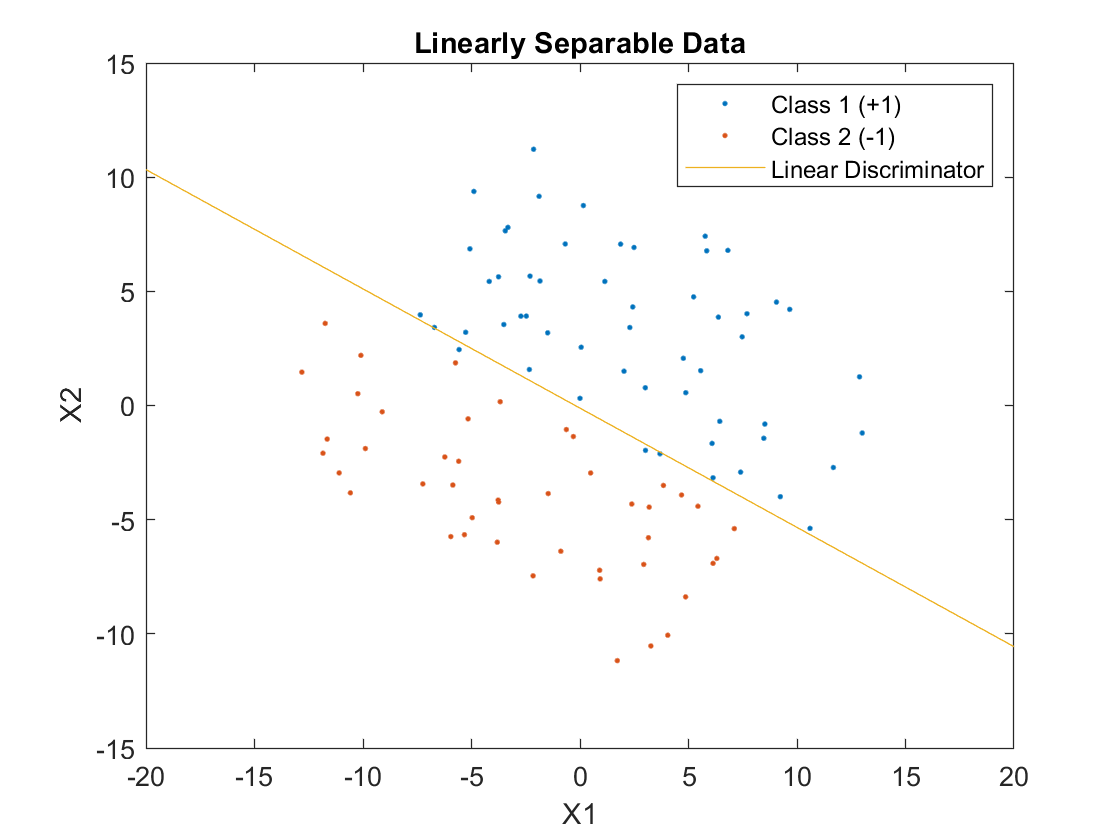

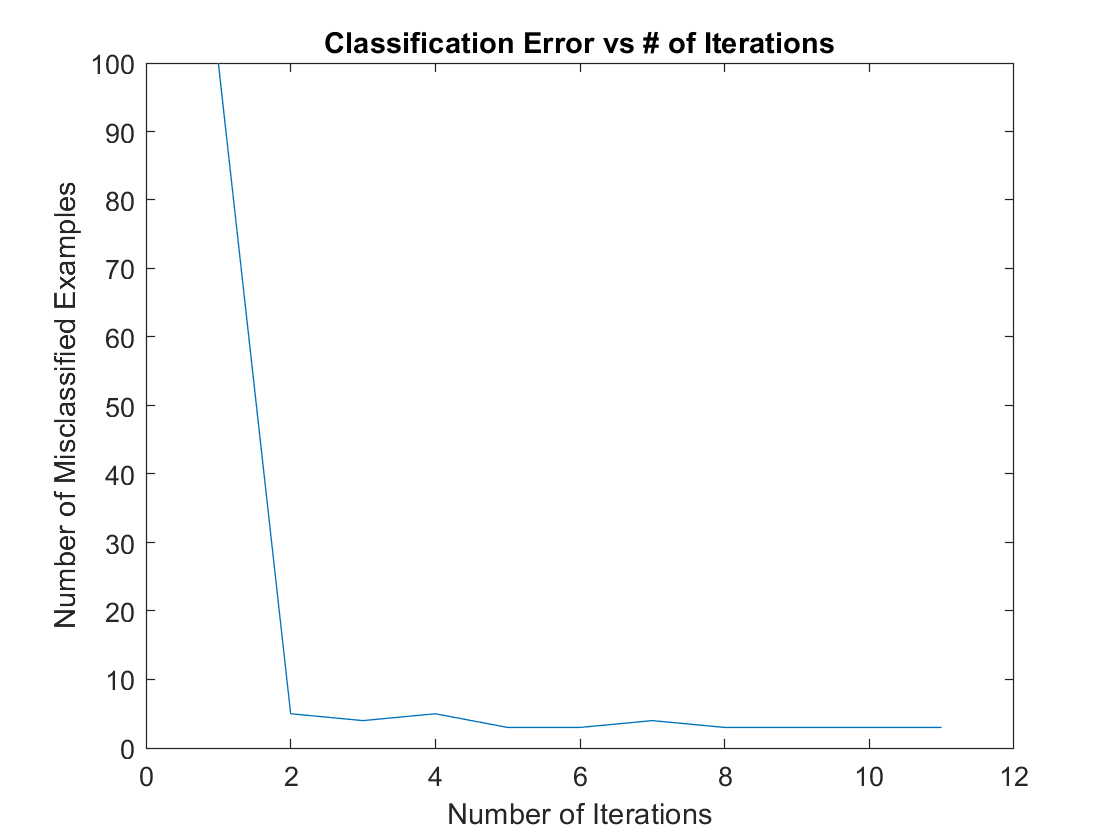

% Assigning Dataset
type = 'linear';
target = sign(H'*x);
pos = target > 0;
neg = target < 0;
iter = 10;
[lw10 lmissed10 lerror10] = batchperc(linear,iter,pos,neg,type,N);

type2 = 'Linearly'

ttl = 'Linearly Separable Data'

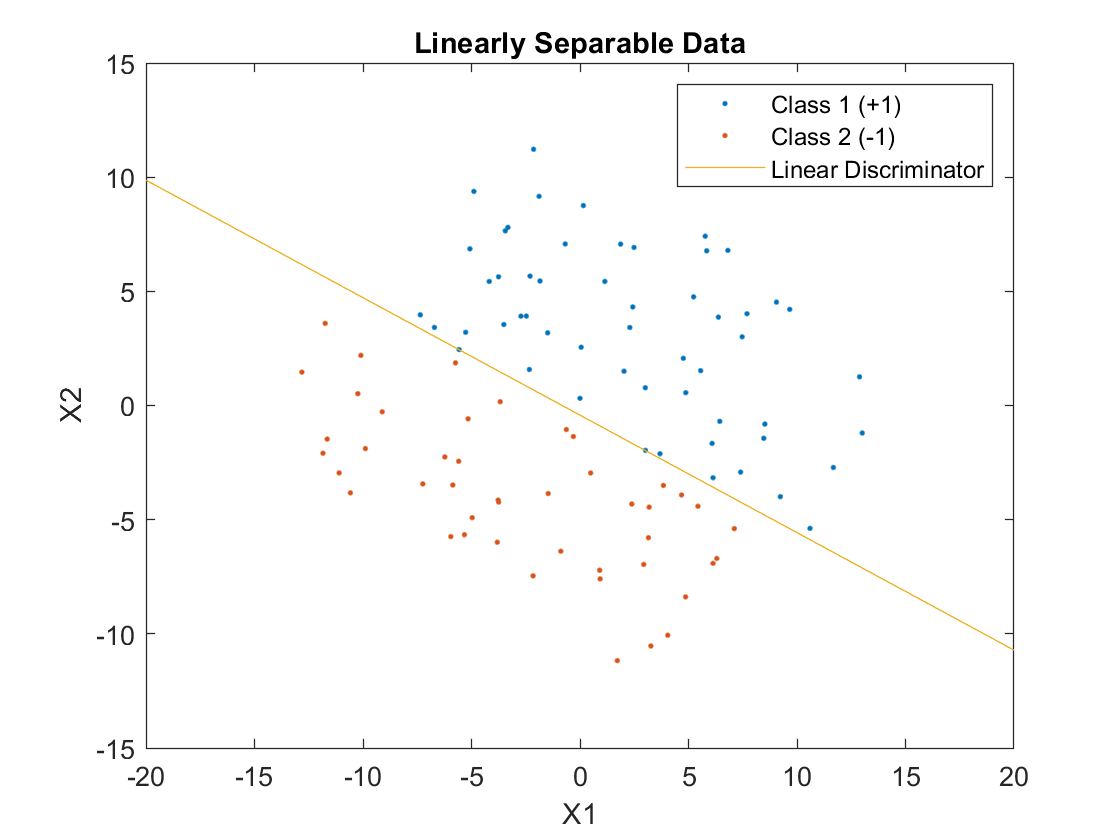

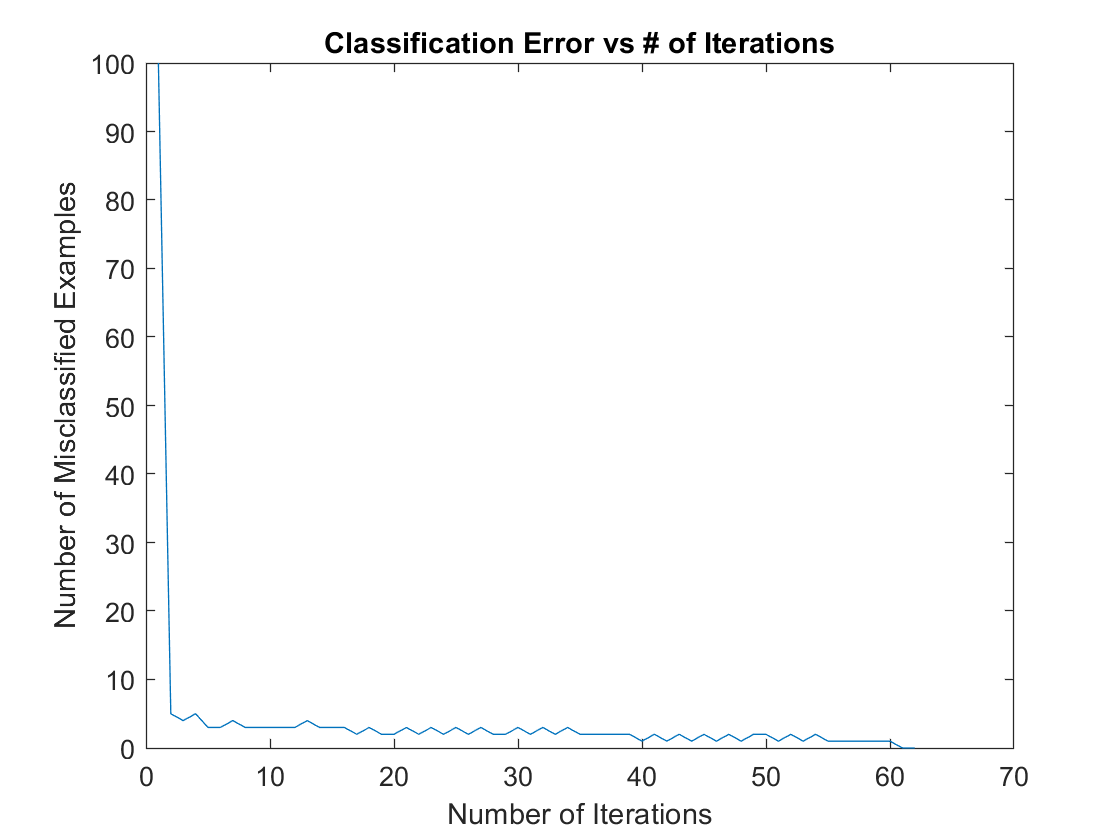

iter = 100;
[lw100 lmissed100 lerror100] = batchperc(linear,iter,pos,neg,type,N);

type2 = 'Non-Linearly'

ttl = 'Non-Linearly Separable Data'

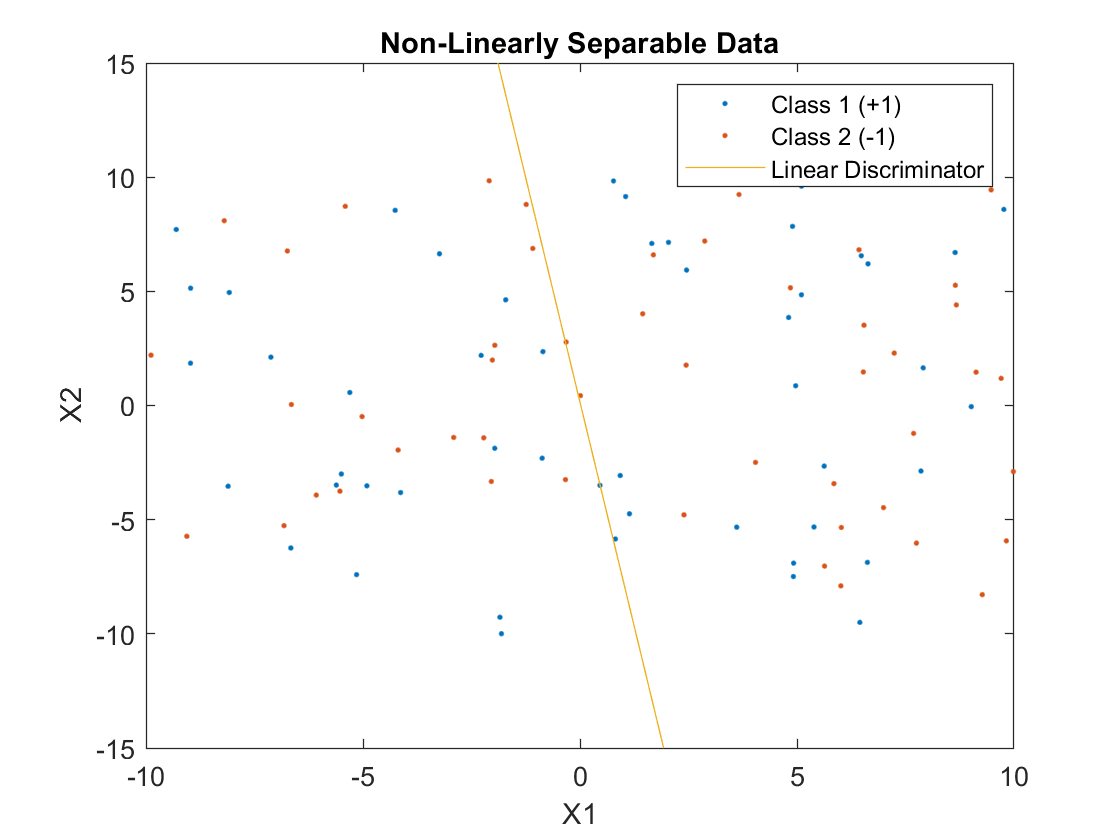

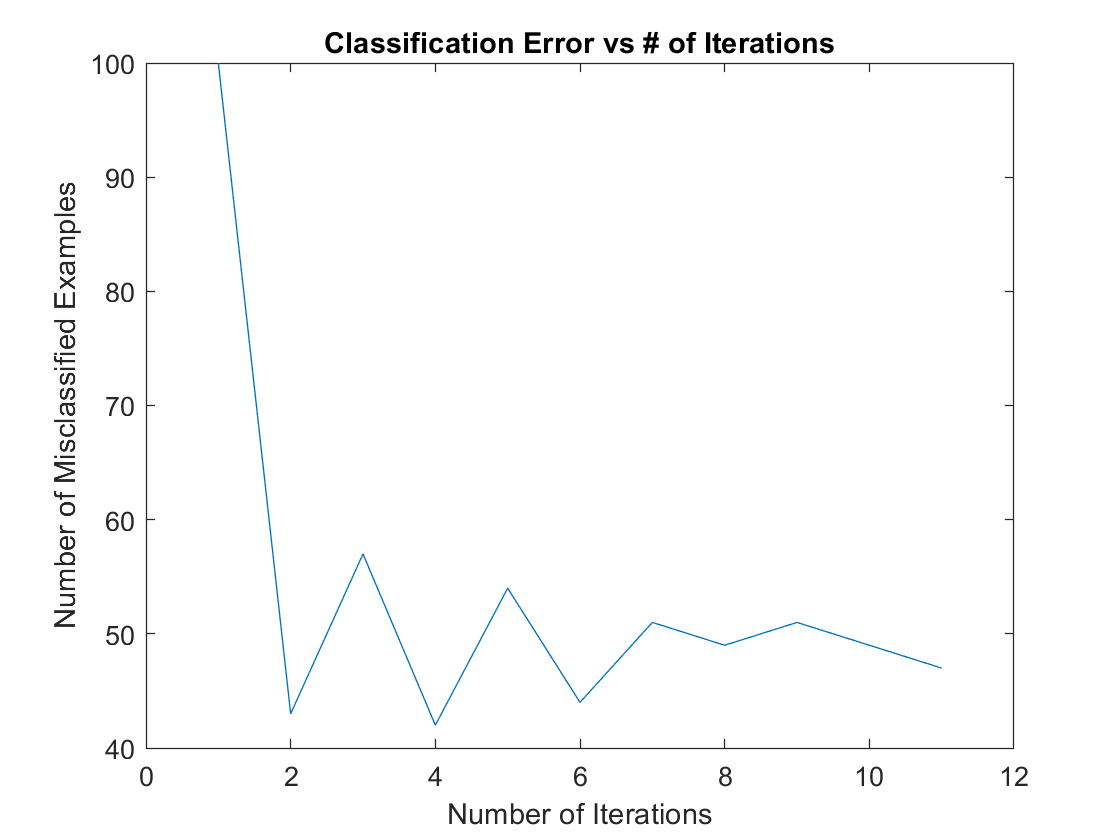

type = 'nonlinear';
pos = 1:0.5*N;
neg = 0.5*N+1:N;
target = [ones(1,N/2),-ones(1,N/2)];
iter = 10;
[nlw10 nlmissed10 nlerror10] = batchperc(nonlinear,iter,pos,neg,type,N);

type2 = 'Non-Linearly'

ttl = 'Non-Linearly Separable Data'

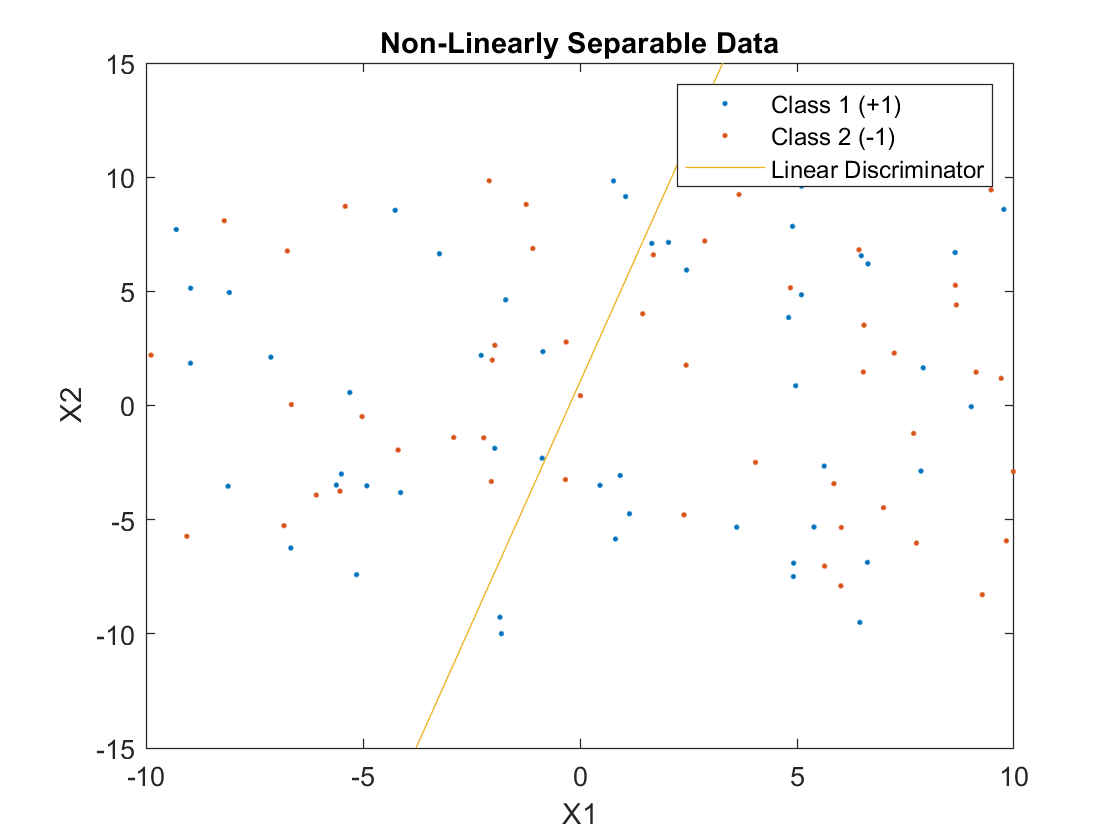

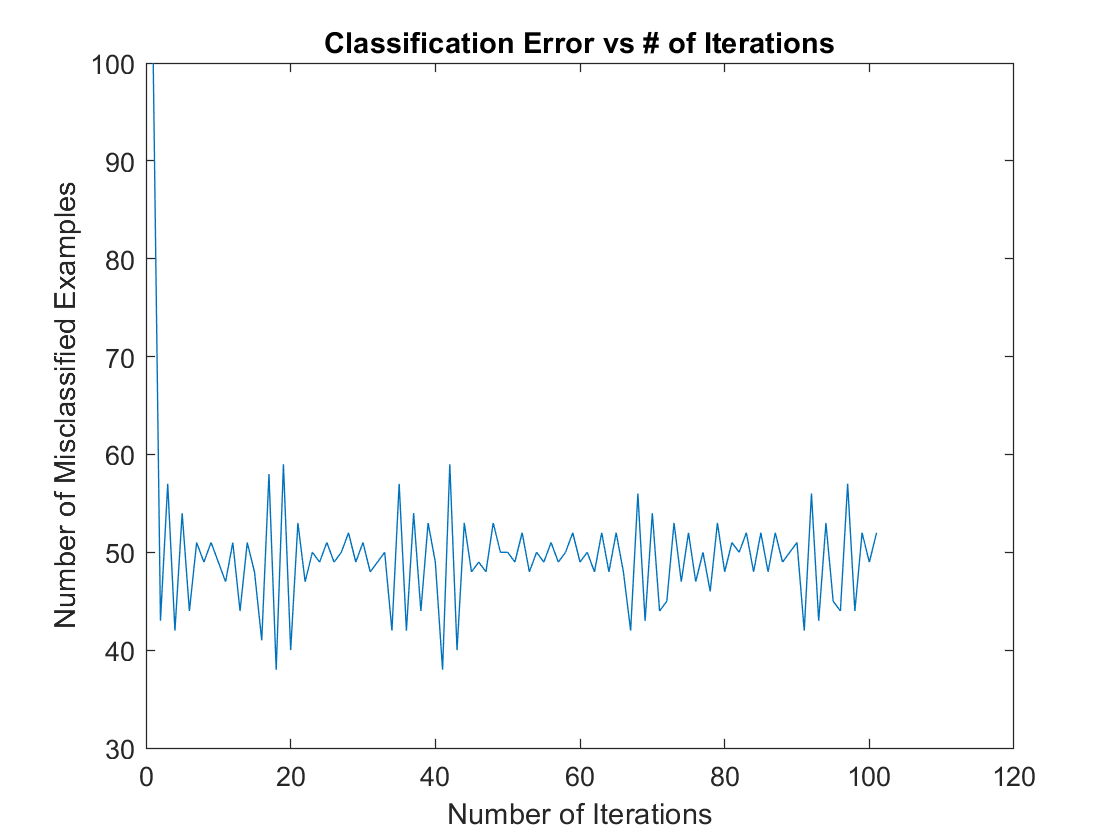

iter = 100;
[nlw100 nlmissed100 nlerror100] = batchperc(nonlinear,iter,pos,neg,type,N);

# Problem 2

## Least Mean Square -- Linear

aa =     0.0480
   -0.0655
    0.1810


type2 = 'Linearly'

ttl = 'Linearly Separable Data'

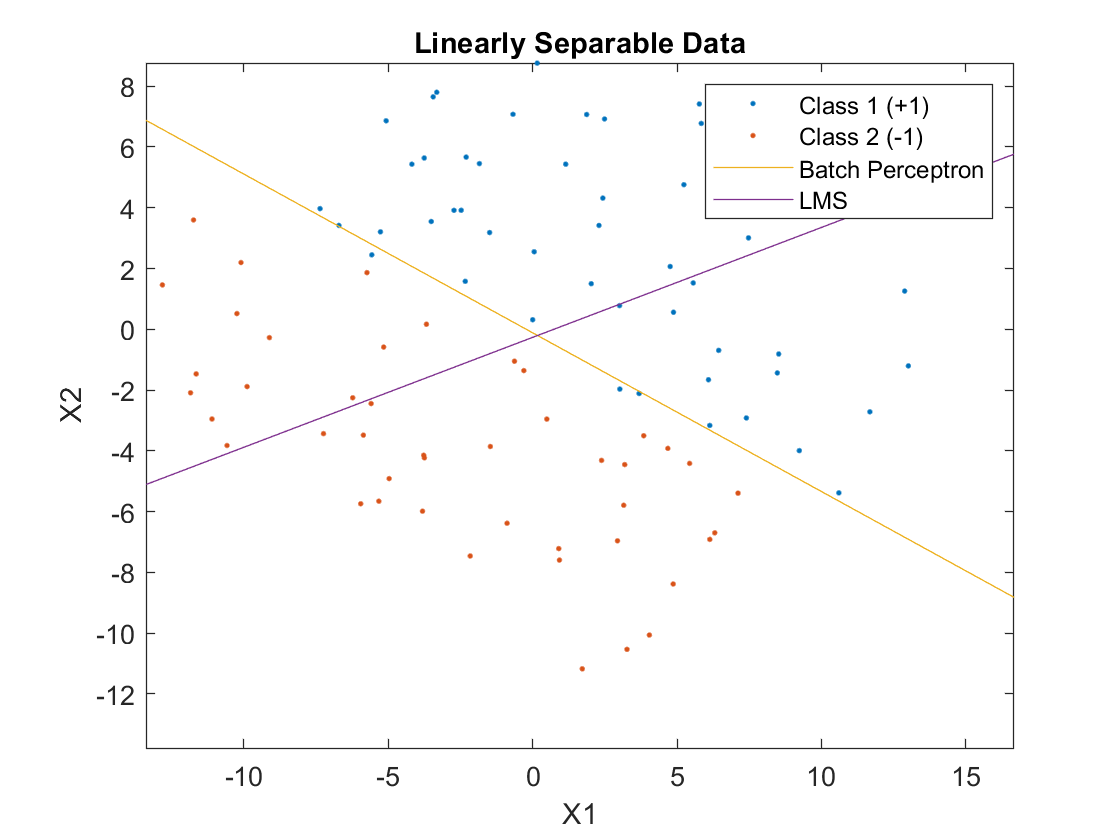

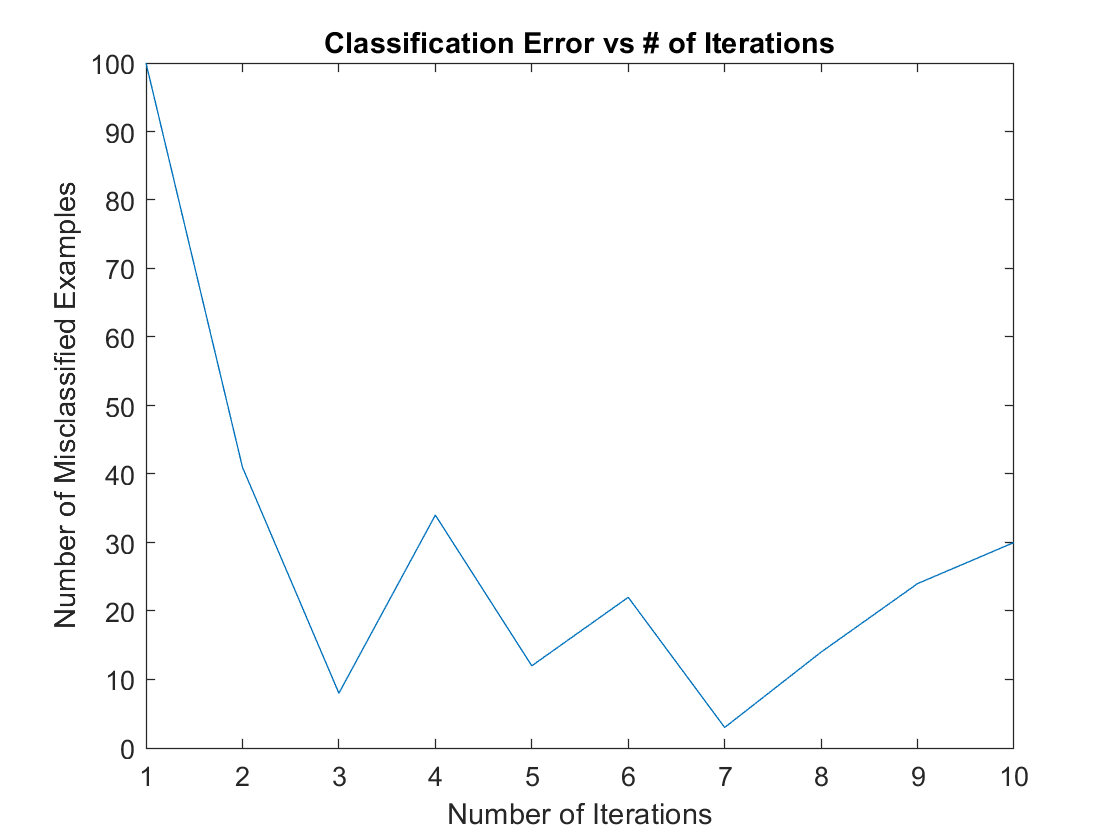

type = 'linear';
target = sign(H'*x);
pos = target > 0;
neg = target < 0;
iter = 10;
[lmsw10 lmsmissed10 lmserror10] = LMS(lw10,x,iter,pos,neg,type,target);

aa =     0.0899
    0.0728
    0.1570


type2 = 'Linearly'

ttl = 'Linearly Separable Data'

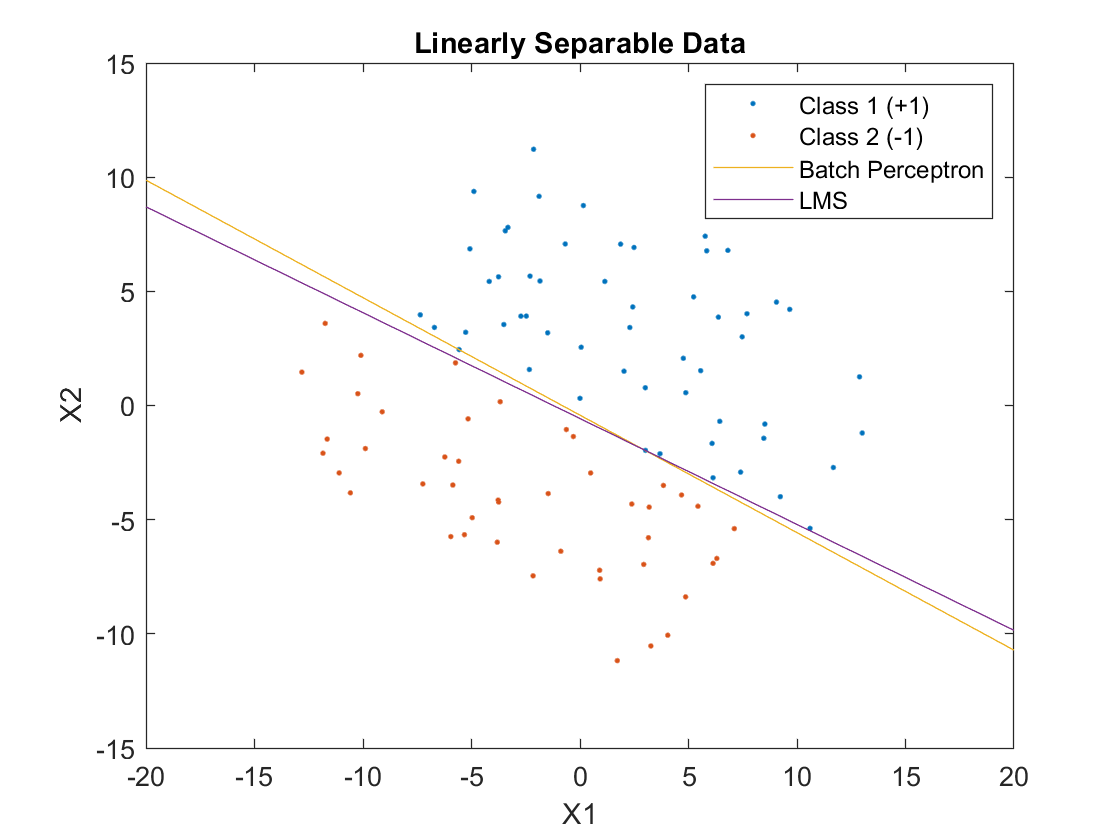

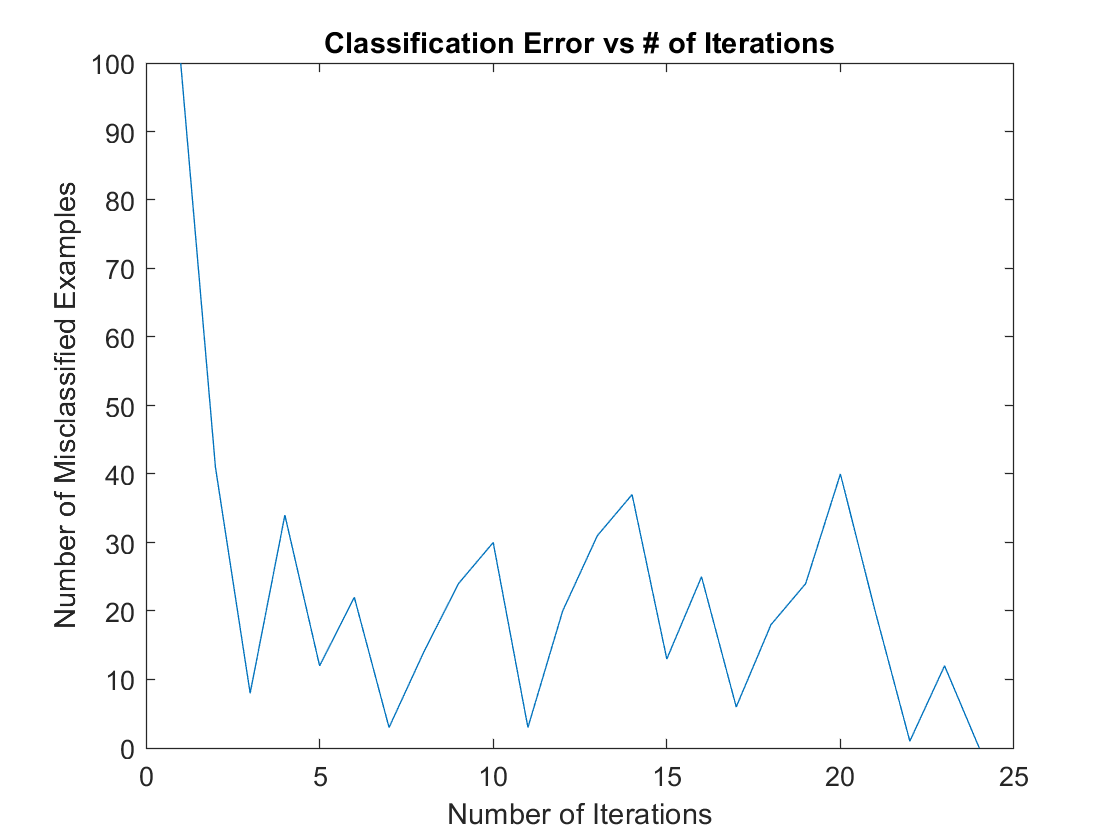

iter = 100;
[lmsw100 lmsmissed100 lmserror100] = LMS(lw100,x,iter,pos,neg,type,target);

aa =     0.1309
   -0.0303
   -0.0151


type2 = 'Non-Linearly'

ttl = 'Non-Linearly Separable Data'

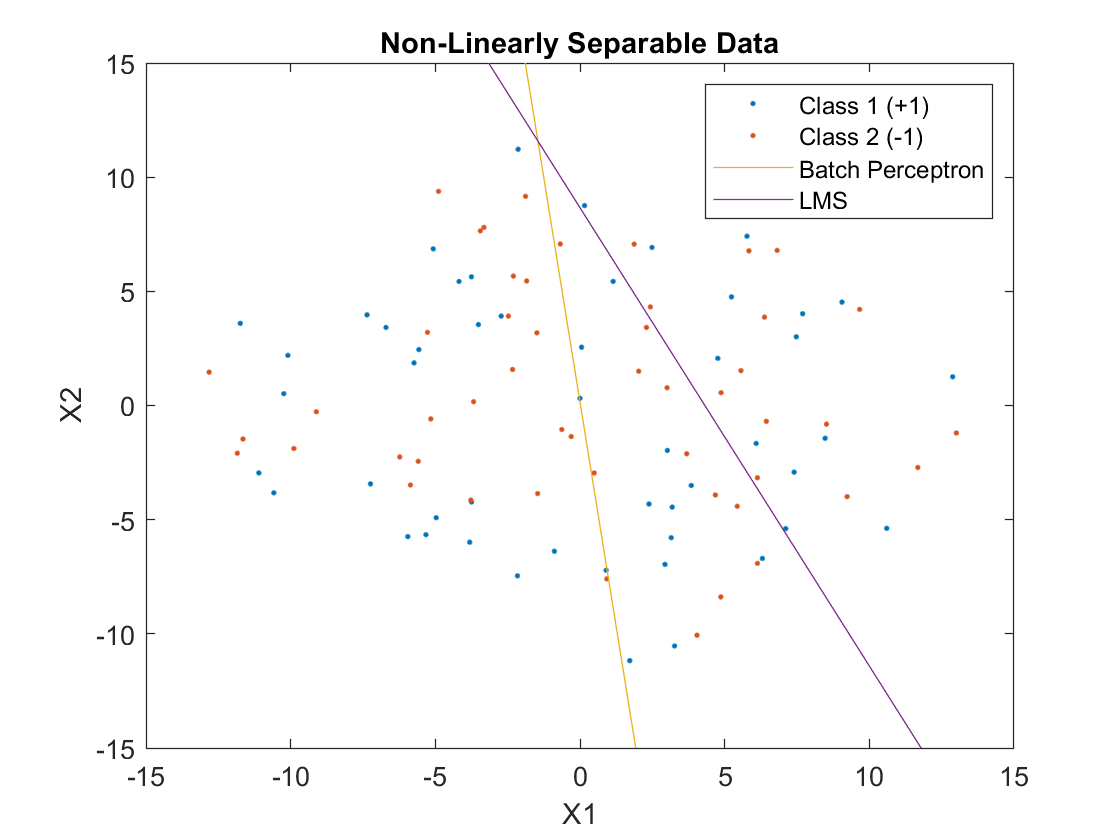

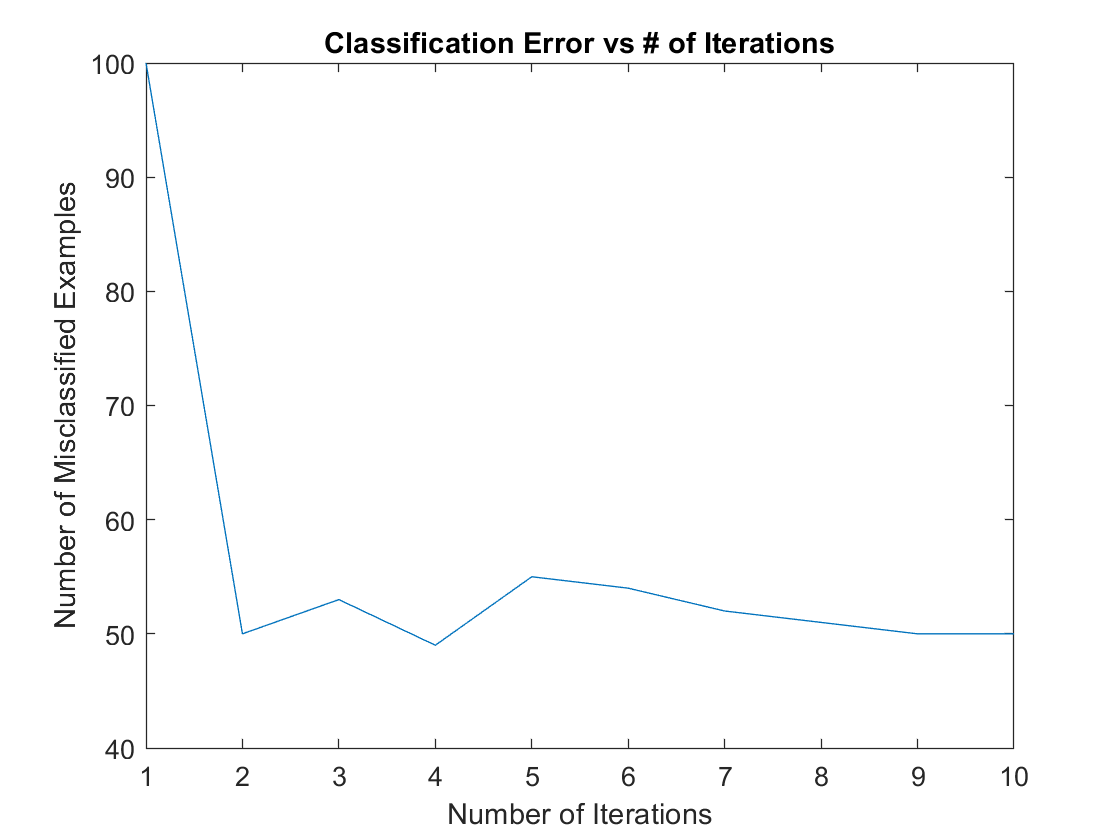

type = 'nonlinear';
pos = 1:0.5*N;
neg = 0.5*N+1:N;
target = [ones(1,N/2),-ones(1,N/2)];
iter = 10;
[nllmsw10 nllmsmissed10 nllmserror10]  = LMS(nlw10,x,iter,pos,neg,type,target);

aa =     0.6130
   -0.0194
    0.0406


type2 = 'Non-Linearly'

ttl = 'Non-Linearly Separable Data'

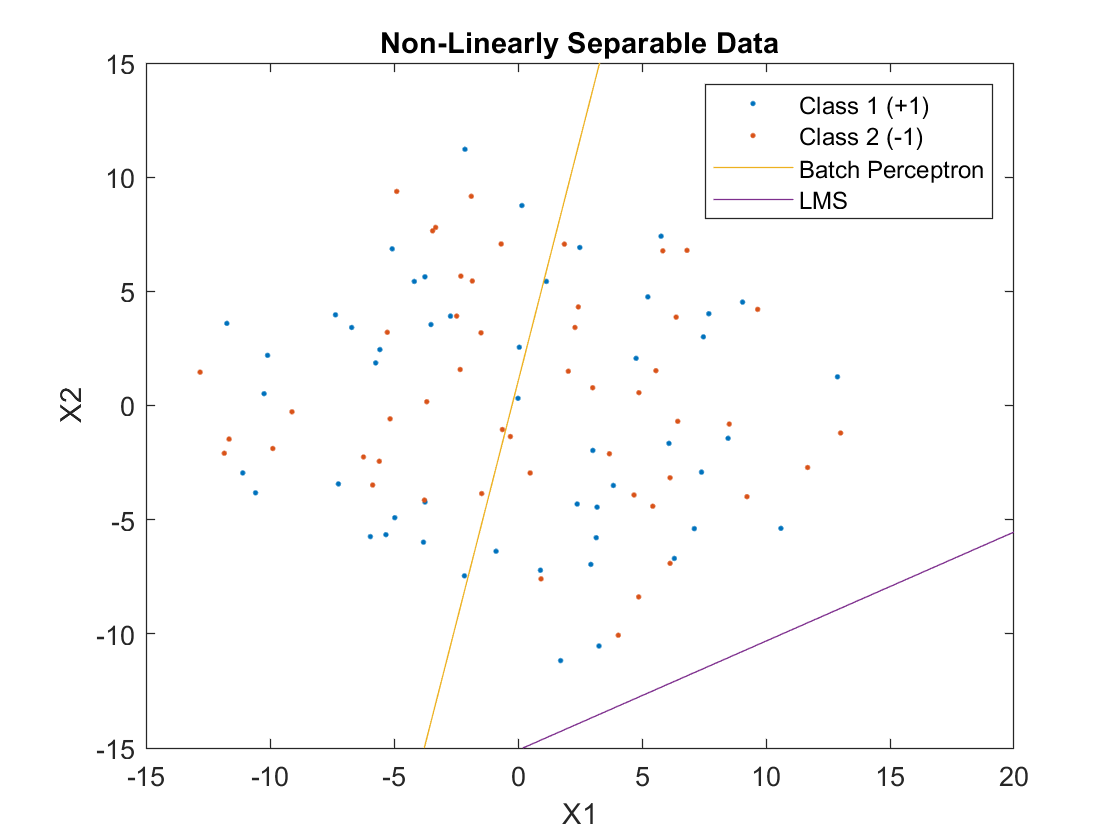

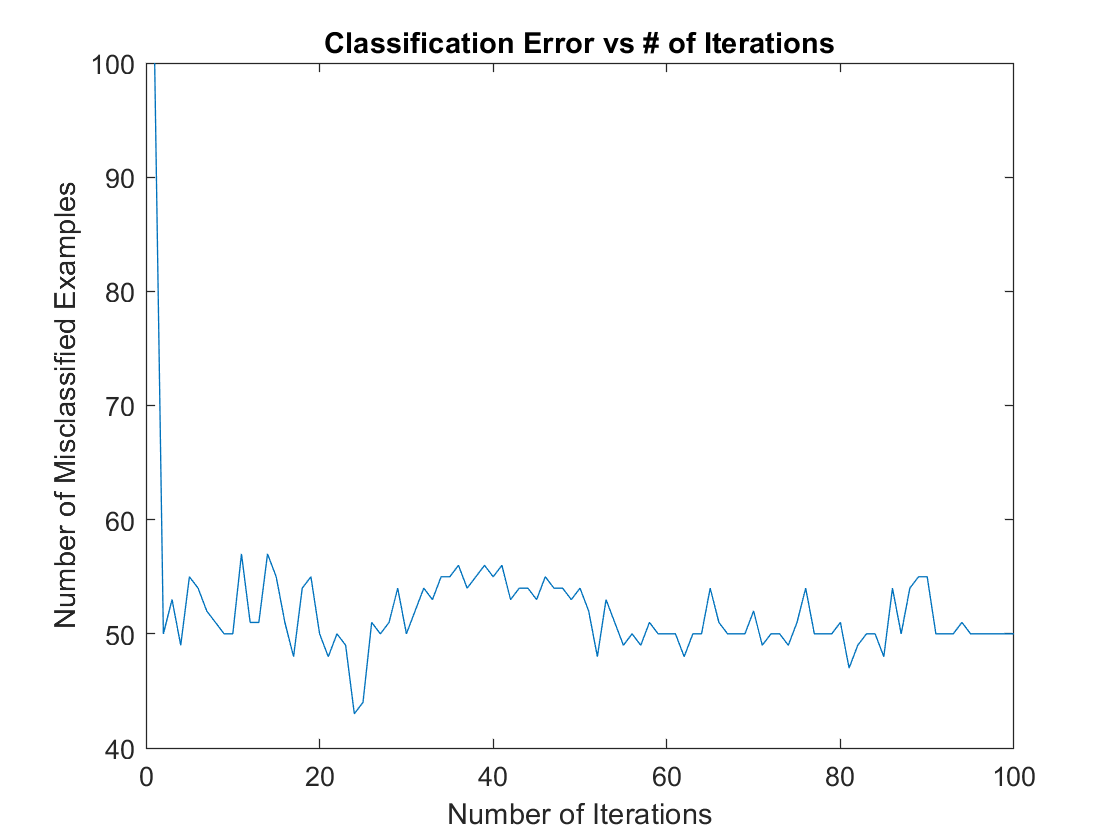

iter = 100;
[nllmsw100 nllmsmissed100 nllmserror100] = LMS(nlw100,x,iter,pos,neg,type,target); 

# Problem 3

tau1 = 200;
tau2 = 200;
lr0 = 1; % learning rate decay initial
dr0 = 2.5; % neighborhood size decay initial

t = 0;
d = zeros(10,10);

dxy = zeros(100,100);
for i = 0:99
    for j = 0:99
        dxy(i+1,j+1) = abs(floor(i/10) - floor(j/10)) + abs(mod(i,10)-mod(j,10));
    end
end
wh1 = zeros(10,10,lambda+1);
wh2 = zeros(10,10,lambda+1);
wh1(:,:,1) = w1;
wh2(:,:,1) = w2;
for i = 0:lambda-1
    for j = 1:10
        for k = 1:10
            d(j,k) = sqrt((D(mod(i,100)+1,1)-wh1(j,k,i+1)).^2+(D(mod(i,100)+1,2)-wh2(j,k,i+1)).^2); % Cartesian distance between data point and weight
        end
    end
    [M,I] = min(d);
    c = find(M == min(M)); % column address where d is minimum
    r = I(c); % row address where d is minimum
    wi1 = wh1(r,c,i+1);
    wi2 = wh2(r,c,i+1);
    lr = lr0*exp(-t/tau1);
    dr = dr0*exp(-t/tau2);
    for j = 1:10
        for k = 1:10
            wh1(j,k,i+2) = wh1(j,k,i+1) + lr*exp(-(dxy(10*(r-1)+c,10*(j-1)+k)^2)/(2*dr^2))*(D(mod(i,100)+1,1)-wh1(j,k,i+1));
            wh2(j,k,i+2) = wh2(j,k,i+1) + lr*exp(-(dxy(10*(r-1)+c,10*(j-1)+k)^2)/(2*dr^2))*(D(mod(i,100)+1,2)-wh2(j,k,i+1));
        end
    end
    t = t+1;
end

figure;
iteration = 1000;
for i = 1:10
    for j = 1:10
        plot(wh1(i,j,iteration+1),wh2(i,j,iteration+1),'b.');
        hold on;
    end
end
xlim([-1 1]);
ylim([-1 1]);
title('Uniform distribution final weights');
xlabel('x');
ylabel('y');
hold off;

figure;
for i = 1:10
    for j = 1:10
        plot(D(:,1),D(:,2),'r.');
        hold on;
    end
end
xlim([-1 1]);
ylim([-1 1]);
xlabel('x');
ylabel('y');
title('Uniform distribution initial weights');
iteration = 1000;
for i = 1:10
    for j = 1:10
        plot(wh1(i,j,iteration+1),wh2(i,j,iteration+1),'b.');
        hold on;
    end
end
xlim([-1 1]);
ylim([-1 1]);
title('Uniform distribution final weights overlap');
xlabel('x');
ylabel('y');
hold off;

figure;
iteration = 1000;
for i = 1:10
    for j = 1:10
        plot(wh1(i,j,iteration+1),wh2(i,j,iteration+1),'b.');
        hold on;
    end
end
xlim([-2 2]);
ylim([-2 2]);
title('Gaussian distribution final weights');
xlabel('x');
ylabel('y');
hold off;

figure;
for i = 1:10
    for j = 1:10
        plot(D(:,1),D(:,2),'r.');
        hold on;
    end
end
iteration = 1000;
for i = 1:10
    for j = 1:10
        plot(wh1(i,j,iteration+1),wh2(i,j,iteration+1),'b-');
        hold on;
    end
end
xlim([-2 2]);
ylim([-2 2]);
title('Gaussian distribution final weights overlap');
xlabel('x');
ylabel('y');
hold off;

# Problem 4

[test_targets, Wh, Wo, J] = backprop(train_patterns, train_targets, test_patterns)

function [w missed error] = batchperc(x,iter,pos,neg,type,N)
    % Weight vector
    eta = 0.01;
    Jp = zeros(3,iter);
    a = zeros(3,iter+1);
    missed = zeros(1,iter+1);
    xc = x;
    xc(:,neg)= -xc(:,neg);
    for k = 1:iter
        ax = (a(:,k)'*xc) <= 0;
        missed(k) = sum(ax);
        Jp(:,k) = sum(xc(:,ax),2);
        a(:,k+1) = a(:,k) + eta*Jp(:,k);
        if norm(eta*Jp(:,k)) < 10e-5
          break
        end
    end
    missed(k+1) = sum(a(:,k+1)'*xc <= 0);
    error = missed(k+1)/N;
    w = a(:,k+1);
    xx = linspace(-20,20);
    m =k+1;
    p = [-a(2,m)/a(3,m) -a(1,m)/a(3,m)];
    yy = polyval(p,xx);
    
    figure()
    plot(x(2,pos),x(3,pos),'.',x(2,neg),x(3,neg),'.',xx,yy);
    ylim([-15,15])
    xlabel('X1')
    ylabel('X2')
    switch type
        case 'linear'
            type2 = 'Linearly'
        case 'nonlinear'
            type2 = 'Non-Linearly'
    end
    
    ttl = sprintf('%s Separable Data',type2)
    title(ttl)
    legend('Class 1 (+1)','Class 2 (-1)','Linear Discriminator')
    fname = sprintf('P1_BatchPerceptron\\P1_%s_perc%d.jpg',type,iter);
    saveas(gcf,fname);
    
    figure()
    plot(missed(1:k+1))
    xlabel('Number of Iterations')
    ylabel('Number of Misclassified Examples')
    title('Classification Error vs # of Iterations')
    fname = sprintf('P1_BatchPerceptron\\P1_%s_miss%d.jpg',type,iter);
    saveas(gcf,fname);
end

function [w missed error] = LMS(aa1,x,iter,pos,neg,type,target)
    % Learning Rate
    eta = 0.01;
    % Weight Vector
    a = zeros(3,iter+1);
    % Actual Targets
    b = target';
    %Jp = zeros(3,iter+1);
    missed = zeros(1,iter+1);
 
    for k = 1:iter
        misx = x(:,(a(:,k)'*x).*b'<= 0);
        N(k) = size(misx,2);
        i = mod(k,N(k));
        if i == 0
            i = N(k);
        elseif N(k) == 0
            break
        end
        ax = a(:,k)'*misx(:,i);
        missed(k) = sum((a(:,k)'*x).*b'<= 0);
        Jmse = (b(i) - ax')*misx(:,i);
        a(:,k+1) = a(:,k) + (eta)*Jmse;
        if norm(eta*Jmse) < 10e-5
          break
        end 
    end
    missed(k) = sum((a(:,k)'*x).*b'<= 0);
    aa = a(:,k)
    error = missed(k)/N(1);
    w = aa;
    p1 = [-aa(2)/aa(3) -aa(1)/aa(3)];
    pa = [-aa1(2)/aa1(3) -aa1(1)/aa1(3)];
    xx = linspace(-20,20);
    yy1 = polyval(p1,xx);
    ya = polyval(pa,xx);
    
    figure()
    plot(x(2,pos),x(3,pos),'.',x(2,neg),x(3,neg),'.',xx,ya,xx,yy1);
    xlabel('X1')
    ylabel('X2')
    ylim([-15,15])
    switch type
        case 'linear'
            type2 = 'Linearly'
        case 'nonlinear'
            type2 = 'Non-Linearly'
    end
        
    ttl = sprintf('%s Separable Data',type2)
    title(ttl)
    legend('Class 1 (+1)','Class 2 (-1)','Batch Perceptron','LMS')
    fname = sprintf('P2_LMS\\P2_%s_LMS%d.jpg',type,iter);
    saveas(gcf,fname);
    
    figure()
    plot(missed(1:k))
    xlabel('Number of Iterations')
    ylabel('Number of Misclassified Examples')
    title('Classification Error vs # of Iterations')
    fname = sprintf('P2_LMS\\P2_%s_miss%d.jpg',type,iter);
    saveas(gcf,fname)
end


function [test_targets, Wh, Wo, J] = backprop(train_patterns, train_targets, test_patterns)

% Classify using a backpropagation network with stochastic learning algorithm
% Inputs:
% 	training_patterns   - Train patterns
%	training_targets	- Train targets
%       test_patterns       - Test  patterns
%	params              - Number of hidden units, Convergence criterion, Convergence rate
%
% Outputs
%	test_targets        - Predicted targets
%       Wh                  - Hidden unit weights
%       Wo                  - Output unit weights
%       J                   - Error throughout the training

%Example:
% load clouds
% t = Backpropagation_Stochastic(patterns, targets, patterns, [5, 0.1, 0.1]);
% disp(mean(t == targets))

Nh = 20; 
Theta = 0.1; 
eta = 0.1;
iter	         = 1;

[Ni, M]          = size(train_patterns);
No		         = 1;

Uc               = length(unique(train_targets));
%Initialize the net: In this implementation there is only one output unit, so there
%will be a weight vector from the hidden units to the output units, and a weight matrix
%from the input units to the hidden units.
%The matrices are defined with one more weight so that there will be a bias
w0		= max(abs(std(train_patterns')'));
Wh		= rand(Nh, Ni+1).*w0*2-w0; %Hidden weights
Wo		= rand(No, Nh+1).*w0*2-w0; %Output weights

Wo    = Wo/mean(std(Wo'))*(Nh+1)^(-0.5);
Wh    = Wh/mean(std(Wh'))*(Ni+1)^(-0.5);

rate	= 10*Theta;
J(1)    = 1e3;

while (rate > Theta)
    %Randomally choose an example
    i	= randperm(M);
    m	= i(1);
    Xm = train_patterns(:,m);
    tk = train_targets(m);
    
    %Forward propagate the input:
    %First to the hidden units
    gh				= Wh*[Xm; 1];
    [y, dfh]		= activation(gh);
    %Now to the output unit
    go				= Wo*[y; 1];
    [zk, dfo]	= activation(go);
    
    %Now, evaluate delta_k at the output: delta_k = (tk-zk)*f'(net)
    delta_k		= (tk - zk).*dfo;
    
    %...and delta_j: delta_j = f'(net)*w_j*delta_k
    delta_j		= dfh'.*Wo(1:end-1).*delta_k;
    
    %w_kj <- w_kj + eta*delta_k*y_j
    Wo				= Wo + eta*delta_k*[y;1]';
    
    %w_ji <- w_ji + eta*delta_j*[Xm;1]
    Wh				= Wh + eta*delta_j'*[Xm;1]';
    
    iter 			= iter + 1;

    %Calculate total error
    J(iter)    = 0;
    for i = 1:M
        J(iter) = J(iter) + (train_targets(i) - activation(Wo*[activation(Wh*[train_patterns(:,i); 1]); 1])).^2;
    end
    J(iter) = J(iter)/M; 
    rate  = abs(J(iter) - J(iter-1))/J(iter-1)*100;
    
    if (iter/100 == floor(iter/100))
        disp(['Iteration ' num2str(iter) ': Total error is ' num2str(J(iter))])
    end
    
end

disp(['Backpropagation converged after ' num2str(iter) ' iterations.'])

%Classify the test patterns
test_targets = zeros(1, size(test_patterns,2));
for i = 1:size(test_patterns,2)
    test_targets(i) = activation(Wo*[activation(Wh*[test_patterns(:,i); 1]); 1]);
end

if (Uc == 2)
    test_targets  = test_targets >0;
end
end

function [f, df] = activation(x)

a = 1.716;
b = 2/3;
f	= a*tanh(b*x);
df	= a*b*sech(b*x).^2;
end
